load tablaOutput.mat
data = [tableOutput.MW(:,2) tableOutput.PDI(:,2)]

data =    14.4958    1.2437
   17.1395    1.2535
   19.8647    1.2741
   22.6679    1.2977
   25.7075    1.3224



mu_v = data(:,1);
std_v =sqrt ((data(:,2) - 1).*mu_v.^2);

cm = parula(50)

cm =     0.2422    0.1504    0.6603
    0.2526    0.1698    0.7201
    0.2618    0.1909    0.7763
    0.2699    0.2121    0.8308
    0.2756    0.2372    0.8753
    0.2794    0.2654    0.9095
    0.2811    0.2942    0.9362
    0.2810    0.3228    0.9579
    0.2787    0.3509    0.9752
    0.2728    0.3795    0.9878


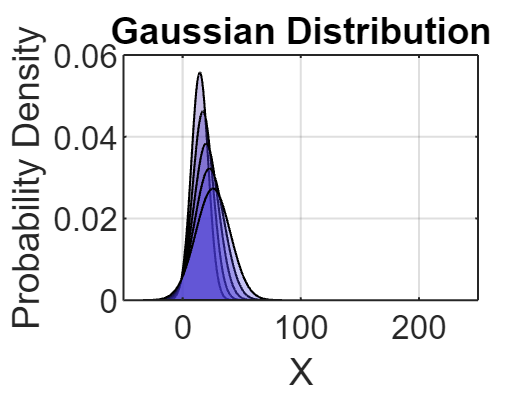



clf
% Generate x-values for plotting
alphas = 0.3;
for i=1:length(data)
    mu = mu_v(i);
    sigma = std_v(i);
x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);
% Compute the probability density function (PDF) of the normal distribution
pdf_normal = normpdf(x, mu, sigma);

% Plot the Gaussian distribution as a filled plot wit transparency
fill(x, pdf_normal,cm(i,:), 'FaceAlpha', alphas);
hold on;

% Plot the PDF curve for reference
%plot(x, pdf_normal, 'b', 'LineWidth', 2);
xlabel('X');
ylabel('Probability Density');
title('Gaussian Distribution');
grid on;

end
xlim([-50 250])